## NN - based PA

clc;
clear;

### Hyper Parameter

P_PA = 10; %PA memory length
num_neuron = 30;

### Load PA input/output data

load('my_dump_file_20bw_15scs_rbs0_rbn_106_cp_20dbm_qpsk.mat');

inDataPA = transpose(dump_pattern.Y_det);
outDataPA = transpose(dump_pattern.X_ref_raw);

num_raw_data = length(inDataPA);
fprintf('num_raw_data: %d\n',num_raw_data);

num_raw_data: 81920


inDataPA_real = real(inDataPA);
inDataPA_imag = imag(inDataPA);
outDataPA_real = real(outDataPA);
outDataPA_imag = imag(outDataPA);

### Arrange NN input and NN target

Considering PA's memory effects, arrange NN inputs with delay line.

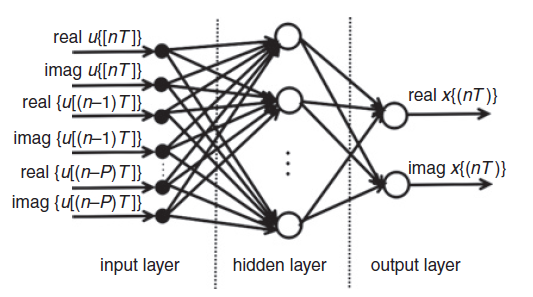

NN_input = zeros(num_raw_data-P_PA+1,2*P_PA);

for i = (0:P_PA-1)
    %NN input
    NN_input(:,i+1) = inDataPA_real(P_PA-i:end-i);
    NN_input(:,i+1+P_PA) = inDataPA_imag(P_PA-i:end-i);
end
    
NN_target = zeros(num_raw_data-P_PA+1,2);   
NN_target(:,1) = outDataPA_real(P_PA:end);
NN_target(:,2) = outDataPA_imag(P_PA:end);

### Training 

#### Using feedforwardnet 

We just use one hidden layer, and we get good performance. The back propagation training function(trainFcn) is Levenberg-Marquardt backpropagation. It combines gradient descent method with Newton method and is specifically designed to minimize sum-of-square error functions. Therefore it is very suitable for our nonlineat data fitting problem.

trainFcn = 'trainlm';
NN_PA = feedforwardnet([num_neuron],trainFcn);
%view(NN);

%NN.divideFcn = 'divideblock'; % default: 'dividerand'
NN_PA.divideParam.trainRatio = 70/100;
NN_PA.divideParam.valRatio = 15/100;
NN_PA.divideParam.testRatio = 15/100;

% hyper parameter
%NN.trainParam.lr = 0.1;  % learning rate
NN_PA.trainParam.epochs = 1000;  % max epochs
%NN.trainParam.max_fail = 100; % Maximum validation failures
%NN.trainParam.min_grad = 1e-8; % Minimum performance gradient

% loss function
NN_PA.performFcn = 'mse';

% activation function: 'purelin':linear/'logsig':sigmoid/'tansig'/'poslin':ReLU
NN_PA.layers{1}.transferFcn = 'tansig';
%NN.layers{2}.transferFcn = 'tansig';
%NN.layers{3}.transferFcn = 'purelin';

% this function requires input and traget's column size must match. tr is
% training record.
[NN_PA,tr] = train(NN_PA,transpose(NN_input),transpose(NN_target));

### Testing (Compare with original PA)

NN_output = NN_PA(transpose(NN_input)); 
NN_output = transpose(NN_output);
NN_output = NN_output(:,1) + 1j * NN_output(:,2);

save NN_PA_model NN_PA;

fprintf("NN_output's length:%d\n",size(NN_output,1));

NN_output's length:81911


%calculate NMSE (NN_PA vs original PA)
NMSE = 10*log10(sum((abs(outDataPA(P_PA:end)-transpose(NN_output))).^2)/sum((abs(outDataPA(P_PA:end))).^2));

fprintf("NMSE:%f\n",NMSE);

NMSE:-42.240504


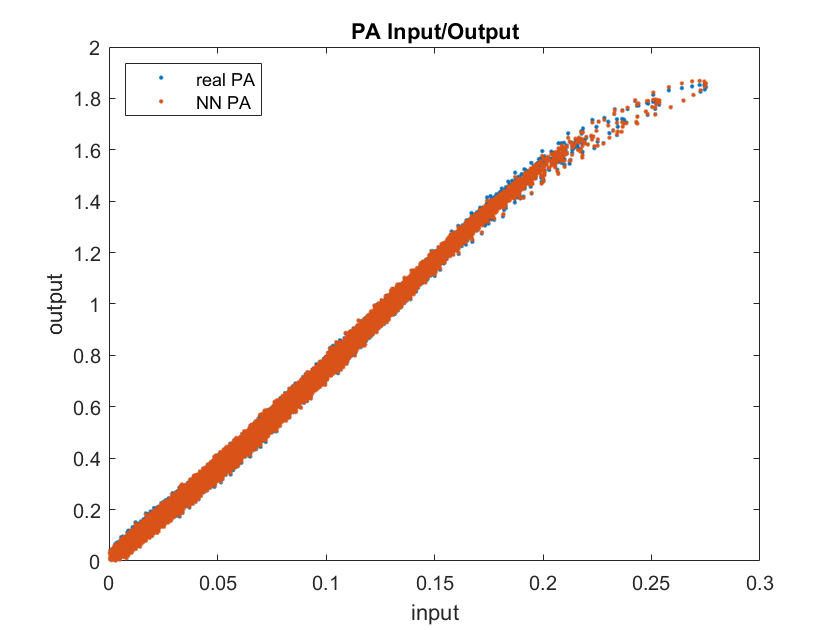

%plot PA Input/Output
figure;
plot(abs(inDataPA),abs(outDataPA),'.');
hold on;
plot(abs(inDataPA(P_PA:end)),abs(NN_output),'.');
title('PA Input/Output');
ylabel('output');
xlabel('input');
legend('real PA','NN PA','Location','northwest');
hold off;